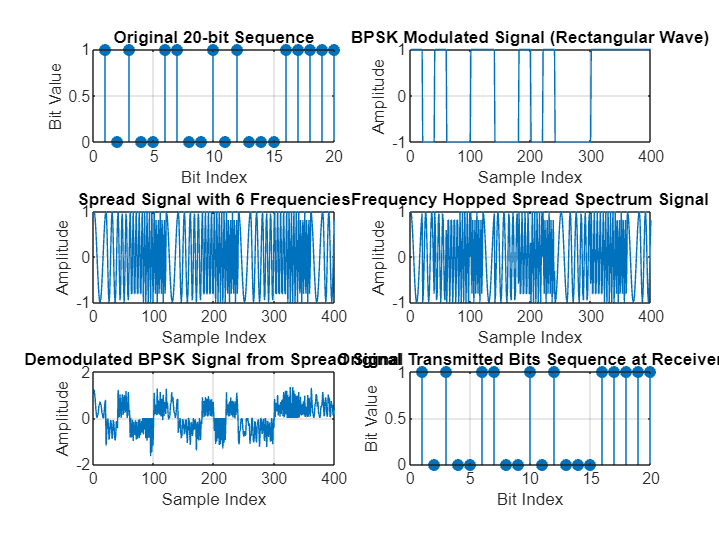

% Parameters
numBits = 20; % Number of bits
numHops = 6; % Number of frequency hops
hopFrequencies = [1, 2, 3, 4, 5, 6] * 1e3; % Frequencies in Hz
hopDuration = 1e-3; % Duration of each hop in seconds
snr = 10; % Signal-to-noise ratio in dB
fs = 20e3; % Sampling frequency in Hz

% Generate random bits  
dataBits = randi([0 1], numBits, 1);

% BPSK Modulation (rectangular wave format)
modulatedData = 2*dataBits - 1; % BPSK mapping (0 -> -1, 1 -> 1)
bpskSignal = repelem(modulatedData, hopDuration*fs); % Create rectangular wave

% Generate FHSS signal
t = (0:1/fs:hopDuration-1/fs)';
fhssSignal = [];
hopSignal = [];
for i = 1:numBits
  hopIdx = mod(i-1, numHops) + 1;
  freq = hopFrequencies(hopIdx);
  carrier = cos(2*pi*freq*t);
  hopSignal = [hopSignal; carrier];
  fhssSignal = [fhssSignal; bpskSignal((i-1)*length(t)+1:i*length(t)) .* carrier];
end

% Transmit over AWGN channel
receivedSignal = awgn(fhssSignal, snr, 'measured');

% Demodulate FHSS signal
demodulatedSignal = [];
receivedBits = zeros(numBits, 1);
for i = 1:numBits
  hopIdx = mod(i-1, numHops) + 1;
  freq = hopFrequencies(hopIdx);
  carrier = cos(2*pi*freq*t);
  segment = receivedSignal((i-1)*length(t)+1:i*length(t));
  demodulated = segment .* carrier;
  demodulatedSignal = [demodulatedSignal; demodulated];
  receivedBits(i) = sum(demodulated) > 0;
end

% Plotting
figure;

% Original 20-bit sequence
subplot(3, 2, 1);
stem(dataBits, 'filled');
title('Original 20-bit Sequence');
xlabel('Bit Index');
ylabel('Bit Value');
grid on;

% BPSK modulated signal (rectangular wave)
subplot(3,2,2);
plot(bpskSignal);
title('BPSK Modulated Signal (Rectangular Wave)');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

% Spread signal with 6 frequencies
subplot(3, 2, 3);
plot(hopSignal);
title('Spread Signal with 6 Frequencies');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

% Frequency hopped spread spectrum signal at transmitter
subplot(3, 2, 4);
plot(fhssSignal);
title('Frequency Hopped Spread Spectrum Signal');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

% Demodulated BPSK signal from widespread signal
subplot(3, 2, 5);
plot(demodulatedSignal);
title('Demodulated BPSK Signal from Spread Signal');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

% Original transmitted bits sequence at the receiver
subplot(3, 2, 6);
stem(receivedBits, 'filled');
title('Original Transmitted Bits Sequence at Receiver');
xlabel('Bit Index');
ylabel('Bit Value');
grid on;


% Calculate and display BER
BER_FHSS = sum(dataBits ~= receivedBits) / numBits;
fprintf('FHSS BER: %e\n', BER_FHSS);

FHSS BER: 0.000000e+00
